1. Să se gasească aproximanta discretă prin metoda celor mai mici pătrate

pentru ponderea w(x)=1 și baza 1; x; x2; : : : ; xn:

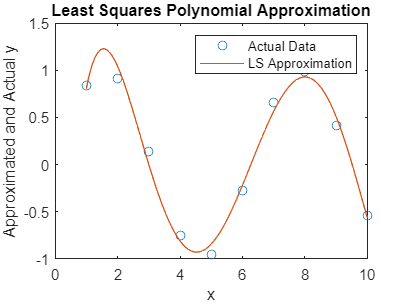

x = 1:10;
y = sin(1:10);
xAprox = linspace(x(1), x(end), 100);  % More idiomatic use of linspace for MATLAB
phi = @(x) [ones(1, length(x)); x; x.^2; x.^3; x.^4;x.^5];
yAprox = LSM(x, y, phi, xAprox);

% Plotting
plot(x, y, 'o', xAprox, yAprox, '-');
title('Least Squares Polynomial Approximation');
xlabel('x');
ylabel('Approximated and Actual y');
legend('Actual Data', 'LS Approximation');

2.

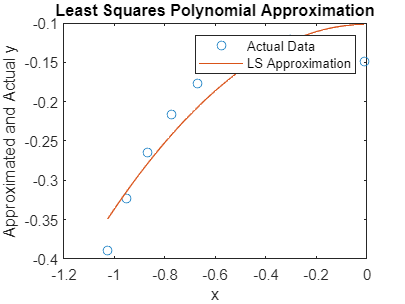

x = [-1.024940 -0.949898 -0.866114 -0.773392 -0.671372 -0.559524 -0.437067 -0.302909 -0.159493 -0.007464];
y = [-0.389269 -0.322894 -0.265256 -0.216557 -0.177152 -0.147582 -0.128618 -0.121353 -0.127348 -0.148895];

% Basis function for elipsoidal model
phi_ellipsoidal = @(x, y) [y.^2; x.*y; x; y; ones(size(x))].';

% Basis function for parabolic model
phi_parabolic = @(y) [y; ones(size(y))].';

% model parabolic
phi = @(x)[ones(1, length(x)); x.^2];

xAprox = x(1):(x(length(x))-x(1))/100:x(length(x));
yAprox = LSM(x, y, phi, xAprox);

plot(x, y, 'o', xAprox, yAprox, '-');
title('Least Squares Polynomial Approximation');
xlabel('x');
ylabel('Approximated and Actual y');
legend('Actual Data', 'LS Approximation');

3.

A = [1 1 1; 1 1 0; 0 1 1; 1 0 0; 0 0 1];
B = [89; 67; 53; 35; 20];
a = linsolve(A, B)

a =    35.1250
   32.5000
   20.6250


sum(a)

ans = 88.2500

4.

x = 1900:10:2010;
y = [75995, 91972, 105710, 123200, 131670, 150700, 179320, 203210, 226510, 249630, 281420, 308790];
phi = @(x)[ones(1, length(x)); x; x.^2; x.^3];

xAprox = x(1):(x(length(x))-x(1))/109:x(length(x));
yAprox = LSM(x, y, phi, xAprox);

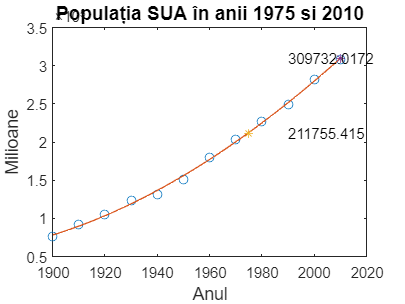


y75 = 1975 - 1900;
estimat75 = yAprox(y75);
y10 = 2010 - 1900;
estimat10 = yAprox(y10);
plot(x, y, 'o', xAprox, yAprox, '-', 1975, estimat75, '*', 2010, estimat10, '*');
text(1990, estimat75, num2str(estimat75));
text(1990, estimat10, num2str(estimat10));
title("Populația SUA în anii 1975 si 2010", "FontSize", 13);
xlabel("Anul", "FontSize", 12);
ylabel("Milioane", "FontSize", 12);


% Datele inițiale
years = 1900:10:2010;
population = [75995, 91972, 105710, 123200, 131670, 150700, 179320, 203210, 226510, 249630, 281420, 308790];  % în mii

% Transformarea datelor
t = years - 1900; % Transformăm anii în ani de la 1900
log_population = log(population);  % Logaritmăm valorile populației

% Model liniarizat pentru regresie
X = [ones(size(t)); t]';
b = X \ log_population';  % Obținem coeficienții modelului liniar

xAprox = years(1):(years(length(years))-years(1))/109:years(length(years));
yAprox = LSM(years, population, phi, xAprox);

% Estimările pentru anii 1975 și 2010
t75 = 1975 - 1900;
t10 = 2010 - 1900;
log_estim75 = b(1) + b(2) * t75;
log_estim10 = b(1) + b(2) * t10;
estim75 = exp(log_estim75);  % Re-transformăm valorile logaritmice înapoi în valori ale populației
estim10 = exp(log_estim10);

% Afișarea rezultatelor
fprintf('Estimarea populației SUA în 1975: %.2f milioane\n', estim75);

Estimarea populației SUA în 1975: 208231.94 milioane


fprintf('Estimarea populației SUA în 2010: %.2f milioane\n', estim10);

Estimarea populației SUA în 2010: 323594.35 milioane


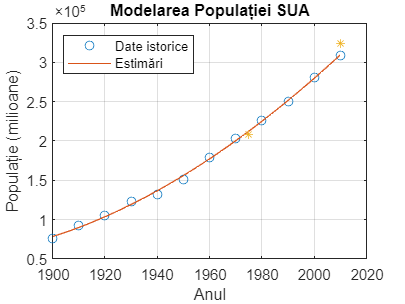


% Plot pentru vizualizare
plot(years, population, 'o', xAprox, yAprox, '-', [1975, 2010], [estim75, estim10], '*');
legend('Date istorice', 'Estimări', 'Location', 'NorthWest');
title('Modelarea Populației SUA');
xlabel('Anul');
ylabel('Populație (milioane)');
grid on;